% clear variables in workspace and close all figures
clearvars; close all;

% reading the data
% data = readtimetable('../Datasets/Saint John/SaintJohnEnergy.xlsx');
data = readtimetable('../Datasets/Ontario/TorontoIESO.xlsx');

TR = timerange('2010-01-01','2019-12-31 23:00:00', "closed");
data = data(TR, :);   % new total dataset

% detecting and removing outliers using Hampel filter
data.DemandMW = hampel(data.DemandMW);
data.Temperature = hampel(data.Temperature);
data.Humidity = hampel(data.Humidity);
data.Dewpoint = hampel(data.Dewpoint);
data.WindDirection = hampel(data.WindDirection);
data.WindSpeed = hampel(data.WindSpeed);

% Normalizing the variables % y = (x - min) / (max - min)

tmp = timetable2table(data);
maxdp = max(table2array(tmp(:, 2:end)));    % takes the max and min of each variable in the dataset
mindp = min(table2array(tmp(:, 2:end)));
tmp.DateTime = [];
normalize = (table2array(tmp) - mindp) ./ (maxdp - mindp);

% creating the normalized dataset
ndata = data;
ndata.DemandMW = normalize(:, 1);
ndata.Temperature = normalize(:, 2);
ndata.Humidity = normalize(:, 3);
ndata.Dewpoint = normalize(:, 4);
ndata.WindDirection = normalize(:, 5);
ndata.WindSpeed = normalize(:, 6);

% norm / denormalization function 
norm = @(x, Max, min)((x-min)/(Max-min)); % y = (x - min) / (max - min)
denorm = @(y,Max,min)(y*(Max-min)+min);
min =mindp(1); Max= maxdp(1);

% clearvars -except data ndata mindp maxdp

% Training and Testing Data Split
TR = timerange('2010-01-01','2019-01-01');  % All of 2010 - 2018
trainvald = ndata(TR, :);   % training data

TR = timerange('2019-01-01','2020-01-01');  % All of 2019
testd = ndata(TR, :);   % testing data 

## Training the Forecasters

### Inputs and Targets Creation

[inputs, blf_outputs, clf_outputs, time_outputs, p] = InputsCreation(ndata);


### Base Load Forecaster CNN training

numResponses=24;
numFeatures=79;

filterSize=[6 5];
numFilters=15;

options = trainingOptions('adam', ...
    'InitialLearnRate',0.001, ...
    'Verbose',false, ...
    'MaxEpochs',300,...
    'Shuffle','never', ...
    'Plots','training-progress'); % sgdm, 


layersCNN = ...
    [ imageInputLayer([numFeatures 1 1]) ... %before
    , convolution2dLayer(filterSize,numFilters,'Padding','same') ...
    , reluLayer ...    
    , maxPooling2dLayer([2 1]) ... %maxPooling2dLayer(2,'Stride',2)
    , fullyConnectedLayer(numResponses) ...
    , regressionLayer] % for 79 inputs

layersCNN =   1x6 Layer array with layers:

     1   ''   Image Input         79x1x1 images with 'zerocenter' normalization
     2   ''   Convolution         15 6x5 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                ReLU
     4   ''   Max Pooling         2x1 max pooling with stride [1  1] and padding [0  0  0  0]
     5   ''   Fully Connected     24 fully connected layer
     6   ''   Regression Output   mean-squared-error


preshapedCnn=reshape(inputs(:),numFeatures,1,1,size(inputs,2));% This is done to convert inputs to 4D so Conv2D can 
% accept it (NumFeatures     1     1   NumbOfDays)

outputsCnn = blf_outputs'; % before % outputs should be NumdDays*NumbOfSamples


% Create training set
train_test_boundaryCnn = size(trainvald,1)/24; %The entire year of 2019 is our test set

trainInd = 1:train_test_boundaryCnn; % index of train samples
trainXblf = preshapedCnn(:,:,:,trainInd);   % input and outputs of the training set
trainblfY = outputsCnn(trainInd,:);% before

testInd = train_test_boundaryCnn+1:size(preshapedCnn,4); % index of test samples
testXblf = preshapedCnn(:,:,:,testInd); % input and outputs of the testing set
testblfY = outputsCnn(testInd,:);% before

% blfnet = trainNetwork(trainXblf,trainblfY,layersCNN,options); % layerscnn before

### Change in the Load Forecaster CNN Training

numResponses=24;
numFeatures=79;

filterSize=[6 5];
numFilters=15;

options = trainingOptions('adam', ...
    'InitialLearnRate',0.001, ...
    'Verbose',false, ...
    'MaxEpochs',300,...
    'Shuffle','never', ...
    'Plots','training-progress'); % sgdm, 


layersCNN = ...
    [ imageInputLayer([numFeatures 1 1]) ... %before
    , convolution2dLayer(filterSize,numFilters,'Padding','same') ...
    , reluLayer ...    
    , maxPooling2dLayer([2 1]) ... %maxPooling2dLayer(2,'Stride',2)
    , fullyConnectedLayer(numResponses) ...
    , regressionLayer] % for 79 inputs

layersCNN =   1x6 Layer array with layers:

     1   ''   Image Input         79x1x1 images with 'zerocenter' normalization
     2   ''   Convolution         15 6x5 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                ReLU
     4   ''   Max Pooling         2x1 max pooling with stride [1  1] and padding [0  0  0  0]
     5   ''   Fully Connected     24 fully connected layer
     6   ''   Regression Output   mean-squared-error


preshapedCnn=reshape(inputs(:),numFeatures,1,1,size(inputs,2));% This is done to convert inputs to 4D so Conv2D can 
% accept it (NumFeatures     1     1   NumbOfDays)

outputsCnn = clf_outputs'; % before % outputs should be NumdDays*NumbOfSamples


% Create training set
train_test_boundaryCnn = size(trainvald,1)/24; %The entire year of 2019 is our test set

trainInd = 1:train_test_boundaryCnn; % index of train samples
trainXclf = preshapedCnn(:,:,:,trainInd);   % input and outputs of the training set
trainclfY = outputsCnn(trainInd,:);% before

testInd = train_test_boundaryCnn+1:size(preshapedCnn,4); % index of test samples
testXclf = preshapedCnn(:,:,:,testInd);
testclfY = outputsCnn(testInd,:);% before


% clfnet = trainNetwork(trainXclf,trainclfY,layersCNN,options); % layerscnn before

## Predict the test dataset

% Generating the inputs for the entire dataset
[inputs, blf_outputs, clf_outputs, time_outputs, p] = InputsCreation(testd);

% Generate BLF forecasts
raw_blf = predict(blfnet,testXblf);   % prediction
yBLF = denorm(raw_blf, Max,min);   
raw_actuals = testblfY;
actuals = denorm(raw_actuals, Max,min);

yBLF = yBLF';
actuals = actuals';

% Generate CLF forecasts
raw_clf = predict(clfnet,testXclf)' +  p(:,1:end-1); 
yCLF = denorm(raw_clf, Max,min); 

% Generate RLS forecasts
days = size(yBLF);
days = days(2);

% calls the rls combiner function
[yRLS, w] = RLS_Combiner(raw_blf', raw_clf, raw_actuals', days); % uses normalized values as inputs
yRLS = denorm(yRLS, Max,min); 


% dates
dtCnn= buffer(datenum(ndata.DateTime),24); 
traindtCnn=(dtCnn(:,trainInd));
testdtCnn=(dtCnn(:,testInd));
time_outputs = datetime(datevec(testdtCnn(:)));

### Calculate errors

[Metrics,eBLF, blf_AEs, blf_APEs, eCLF, clf_AEs, clf_APEs,...
eRLS, rls_AEs, rls_APEs, blf_MAPE, clf_MAPE, rls_MAPE] = ErrorMetrics(actuals, yBLF, yCLF, yRLS);

Metrics

Metrics = 6×4 table
                   Metrics                     BLF       CLF        RLS  
    ______________________________________    ______    ______    _______

    {'MAPE - Mean Absolute Percent Error'}     2.465    2.3083     2.2697
    {'ME - Mean Error'                   }    66.274    32.815    0.49219
    {'MAE - Mean Absolute Error'         }    143.16    134.07     131.94
    {'MSE - Mean Squared Error'          }     41528     37451      38215
    {'RMSE - Root Mean Squared Error'    }    203.78    193.52     195.49
    {'Standard Deviation'                }    192.72    190.73      195.5


### Plots of the Test dataset

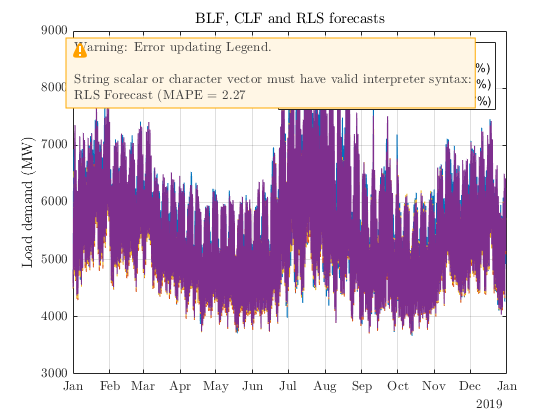

figure;

% plot actual values
plot(time_outputs, actuals(:), 'DisplayName','Actual Values')
title('BLF, CLF and RLS forecasts')
ylabel('Load demand (MW)')
grid on; 
hold on;

% plot blf forecast
DisplayName = num2str(blf_MAPE, 'BLF Forecast (MAPE = %.2f%%)');
plot(time_outputs,yBLF(:), 'DisplayName', DisplayName)

% plot clf forecast
DisplayName = num2str(clf_MAPE, 'CLF Forecast (MAPE = %.2f%%)');
plot(time_outputs,yCLF(:), 'DisplayName', DisplayName)

% plot rls forecast
DisplayName = num2str(rls_MAPE, 'RLS Forecast (MAPE = %.2f%%)');
plot(time_outputs,yRLS(:), 'DisplayName', DisplayName)
legend('show')

## %% To be continued

## Performance Analysis of the Algorithms

### Hourly Horizon

% helps to align the y axes
tmp = [eBLF; eCLF; eRLS];
ymax = max(tmp(:))+50;
ymin = min(tmp(:))+50;

Array indices must be positive integers or logical values.

% ylim([ymin ymax])


figure;
time24 = time_outputs.Hour + 1; % Time = 1...24 hrs
t = tiledlayout(2,3);
t.Padding = 'compact';     % uses all the spaces in the figure window
t.TileSpacing = 'compact';
sgt = sgtitle("Performance of the Algorithms - Errors, Absolute Errors, Absolute Percent Errors - Hourly horizons");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');


% Box plots of the error distribution
nexttile
% sp(1) = nexttile;
boxplot(eBLF(:), time24)
ylim([ymin ymax])
title('Base Load Forecaster (BLF)')

nexttile
% sp(2) = nexttile;
boxplot(eCLF(:), time24)
ylim([ymin ymax])
title('Change in Load Forecaster (CLF)')

nexttile
% sp(3) = nexttile;
boxplot(eRLS(:), time24)
ylim([ymin ymax])
title('Recursive Least Squares Combination (RLS)')
% linkaxes(sp)


% Absolute Errors plots     % divided by 100, so I can fit multiple charts
sp(1) = nexttile;
stats = grpstats(blf_AEs(:)/100, time_outputs.Hour, "mean");
plot(stats, '-o')
% legend('BLF Absolute Errors')
grid
hold on

sp(2) = nexttile;
stats = grpstats(clf_AEs(:)/100, time_outputs.Hour, "mean");
plot(stats, '-o')
% legend('CLF Absolute Errors')
grid
hold on

sp(3) = nexttile;
stats = grpstats(rls_AEs(:)/100, time_outputs.Hour, "mean");
plot(stats, '-o')
% legend('RLS Absolute Errors')
grid
hold on
% linkaxes(sp)
clear sp


% Absolute Percent Errors plot
sp(1) = nexttile(4);
stats = grpstats(blf_APEs(:), time_outputs.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('BLF Absolute Errors / 100','BLF Absolute Percent Errors', 'Location','northwest')
grid on

sp(2) = nexttile(5);
stats = grpstats(clf_APEs(:), time_outputs.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('CLF Absolute Errors / 100','CLF Absolute Percent Errors', 'Location','northwest')
grid on

sp(3) = nexttile(6);
stats = grpstats(rls_APEs(:), time_outputs.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('RLS Absolute Errors / 100','RLS Absolute Percent Errors', 'Location','northwest')
grid on
linkaxes(sp)

### Daily Horizon

% helps to align the y axes
tmp = [eBLF; eCLF; eRLS];
ymax = max(tmp(:))+50;
ymin = min(tmp(:))-50;
% ylim([ymin ymax])


figure;
[dnum, dname] = weekday(time_outputs, 'long');
labels = {'Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday', 'Saturday', 'Sunday'};

t = tiledlayout(2,3);
t.Padding = 'compact';     % uses all the spaces in the figure window
t.TileSpacing = 'compact';
sgt = sgtitle("Performance of the Algorithms - Errors, Absolute Errors, Absolute Percent Errors - Daily horizons");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');


% Box plots of the error distribution
xtick = [7,1,2,3,4,5,6];    % the position we want them displayed as, i.e Mon - Sun

nexttile
% sp(1) = nexttile;
boxplot(eBLF(:), dnum,'positions', xtick)
set(gca, 'XTickLabel', labels)
ylim([ymin ymax])
title('Base Load Forecaster (BLF)')

nexttile
% sp(2) = nexttile;
boxplot(eCLF(:), dnum,'positions', xtick)
set(gca, 'XTickLabel', labels)
ylim([ymin ymax])
title('Change in Load Forecaster (CLF)')

nexttile
% sp(3) = nexttile;
boxplot(eRLS(:), dnum,'positions', xtick)
set(gca, 'XTickLabel', labels)
ylim([ymin ymax])
title('Recursive Least Squares Combination (RLS)')
% linkaxes(sp)


% Absolute Errors plots     % divided by 100, so I can fit multiple charts
sp(1) = nexttile;
stats = grpstats(blf_AEs(:)/100, dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca, "XTickLabel", labels)
% legend('BLF Absolute Errors')
grid
hold on

sp(2) = nexttile;
stats = grpstats(clf_AEs(:)/100, dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca, "XTickLabel", labels)
% legend('CLF Absolute Errors')
grid
hold on

sp(3) = nexttile;
stats = grpstats(rls_AEs(:)/100, dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca, "XTickLabel", labels)
% legend('RLS Absolute Errors')
grid
hold on
% linkaxes(sp)
clear sp


% Absolute Percent Errors plot
sp(1) = nexttile(4);
stats = grpstats(blf_APEs(:), dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labels)
legend('BLF Absolute Errors / 100','BLF Absolute Percent Errors', 'Location','northeast')
grid on

sp(2) = nexttile(5);
stats = grpstats(clf_APEs(:), dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labels)
legend('CLF Absolute Errors / 100','CLF Absolute Percent Errors', 'Location','northeast')
grid on

sp(3) = nexttile(6);
stats = grpstats(rls_APEs(:), dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labels)
legend('RLS Absolute Errors / 100','RLS Absolute Percent Errors', 'Location','northeast')
grid on
linkaxes(sp, 'y')

### Monthly Horizon

% helps to align the y axes
tmp = [eBLF; eCLF;eRLS];
ymax = max(tmp(:))+50;
ymin = min(tmp(:))-50;
% ylim([ymin ymax])


figure;
labels = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug',...
          'Sep', 'Oct', 'Nov', 'Dec'};

t = tiledlayout(2,3);
t.Padding = 'compact';     % uses all the spaces in the figure window
t.TileSpacing = 'compact';
sgt = sgtitle("Performance of the Algorithms - Errors, Absolute Errors, Absolute Percent Errors - Monthly horizons");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');


% Box plots of the error distribution
nexttile
% sp(1) = nexttile;
boxplot(eBLF(:), time_outputs.Month, 'Labels', labels)
ylim([ymin ymax])
title('Base Load Forecaster (BLF)')

nexttile
% sp(2) = nexttile;
boxplot(eCLF(:), time_outputs.Month, 'Labels', labels)
ylim([ymin ymax])
title('Change in Load Forecaster (CLF)')

nexttile
% sp(3) = nexttile;
boxplot(eRLS(:), time_outputs.Month, 'Labels', labels)
ylim([ymin ymax])
title('Recursive Least Squares Combination (RLS)')
% linkaxes(sp)


% Absolute Errors plots     % divided by 100, so I can fit multiple charts
sp(1) = nexttile;
stats = grpstats(blf_AEs(:)/100, time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
% legend('BLF Absolute Errors')
grid
hold on

sp(2) = nexttile;
stats = grpstats(clf_AEs(:)/100, time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
% legend('CLF Absolute Errors')
grid
hold on

sp(3) = nexttile;
stats = grpstats(rls_AEs(:)/100, time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
% legend('RLS Absolute Errors')
grid
hold on
% linkaxes(sp)
clear sp


% Absolute Percent Errors plot
sp(1) = nexttile(4);
stats = grpstats(blf_APEs(:), time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
legend('BLF Absolute Errors / 100','BLF Absolute Percent Errors', 'Location','northwest')
grid on

sp(2) = nexttile(5);
stats = grpstats(clf_APEs(:), time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
legend('CLF Absolute Errors / 100','CLF Absolute Percent Errors', 'Location','northwest')
grid on

sp(3) = nexttile(6);
stats = grpstats(rls_APEs(:), time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
legend('RLS Absolute Errors / 100','RLS Absolute Percent Errors', 'Location','northwest')
grid on
linkaxes(sp, 'y')